# MXB201 Exercises 4

## Theory

T1.  Prove that  if $v_1$ and $v_2$ are eigenvectors of a symmetric matrix associated with eigenjvalues $\lambda_1$ and $\lambda_2$ respectively, with$\lambda_1 \neq \lambda_2$, then $v_1 \cdot v_2 = 0$.

T2.  Let $A \in \mathbb{R}^{n \times n}$.  If $(\lambda, v)$ is an eigenpair of $A$, prove that $(\lambda^k, v)$ is an eigenpair of $A^k$  ($k$ is a positive integer).

T3.  Let $A \in \mathbb{R}^{m \times n}$.  Prove that $A^T A$ and $AA^T$ have the same nonzero eigenvalues.Try a couple of random matrix examples in MATLAB to convince yourself first.

T4.  Show that the eigenvalues of $A^TA$ are all non-negative.  That is, $A^TA$ is symmetric positive semi-definite.

T5.  Show that if $A$ has full column rank then $A^TA$ is symmetric positive definite.

## Practice

P1.  For each of these matrices, run `animate_matrix(A)` and deduce as much as you can about the eigenvalues and eigenvectors of $A$.  Then, calculate them (if you want the practice) or get MATLAB to do it, to confirm.

A1 = sym([2, 0 ; 0, 1])

$$A1 = \left(\begin{array}{cc} 2 & 0\\ 0 & 1 \end{array}\right)$$

A2 = sym([2, 0 ; 0,-1])

$$A2 = \left(\begin{array}{cc} 2 & 0\\ 0 & -1 \end{array}\right)$$

A3 = sym([0, 1 ; 1, 0])

$$A3 = \left(\begin{array}{cc} 0 & 1\\ 1 & 0 \end{array}\right)$$

A4 = sym([0, 1 ;-1, 0])

$$A4 = \left(\begin{array}{cc} 0 & 1\\ -1 & 0 \end{array}\right)$$

A5 = sym([1, 1 ; 1, 1])

$$A5 = \left(\begin{array}{cc} 1 & 1\\ 1 & 1 \end{array}\right)$$

A6 = sym([1, 1 ; 0, 1])

$$A6 = \left(\begin{array}{cc} 1 & 1\\ 0 & 1 \end{array}\right)$$

P2.  Find the orthogonal diagonalisation of

A = sym([
     7    -1     1     0    -2
    -1     8     2     0     1
     1     2     8     0    -1
     0     0     0    10     0
    -2     1    -1     0     7])

$$A = \left(\begin{array}{ccccc} 7 & -1 & 1 & 0 & -2\\ -1 & 8 & 2 & 0 & 1\\ 1 & 2 & 8 & 0 & -1\\ 0 & 0 & 0 & 10 & 0\\ -2 & 1 & -1 & 0 & 7 \end{array}\right)$$

P3.  Anton 5.1.  Questions 5, 7, 9, 11, 25, 27, 33, 35, TF.

P4.  Anton 5.2.  Questions 5, 7, 9, 11, 13, TF.

P5.  For each of the matrices in P1, if possible use the diagonalisation to calculate $\exp(At)$.

P6.  Verify the Cayley-Hamilton theorem for

A = sym([0 0 -2 ; 1 2 1 ; 1 0 3])

$$A = \left(\begin{array}{ccc} 0 & 0 & -2\\ 1 & 2 & 1\\ 1 & 0 & 3 \end{array}\right)$$

Hence express $A^3$ in terms of lower matrix powers.

## Exploration

E1.  The equation of an ellipse in $(x_1, x_2)$ coordinate space, centred at the origin, but rotated, is

$A{x_1}^2 + Bx_1\,x_2 + C{x_2}^2 = 1$        (1)

Show how this can be written in matrix-vector form as


$$x^T A x = 1$$


for $x = \left[\matrix{x_1\cr x_2}\right]$ and some suitable matrix $A \in \mathbb{R}^{2 \times 2}$.  What form does this matrix take?

Diagonalise the matrix as $A = QDQ^T$ (why is this always possible?), and show how this allows (1) to be written in standard form in terms of transformed coordinates $({y_1}, {y_2})$


$$A\prime {y_1}^2 + C\prime {y_2}^2 = 1$$


for new coefficients $A\prime$ and $C\prime$.

Use this technique to determine the semimajor and semiminor axis lengths, and the angle of rotation, for the ellipse


$$5{x_1}^2 + 4x_1\,x_2 + 8{x_2}^2 = 1$$


Here it is pictured.

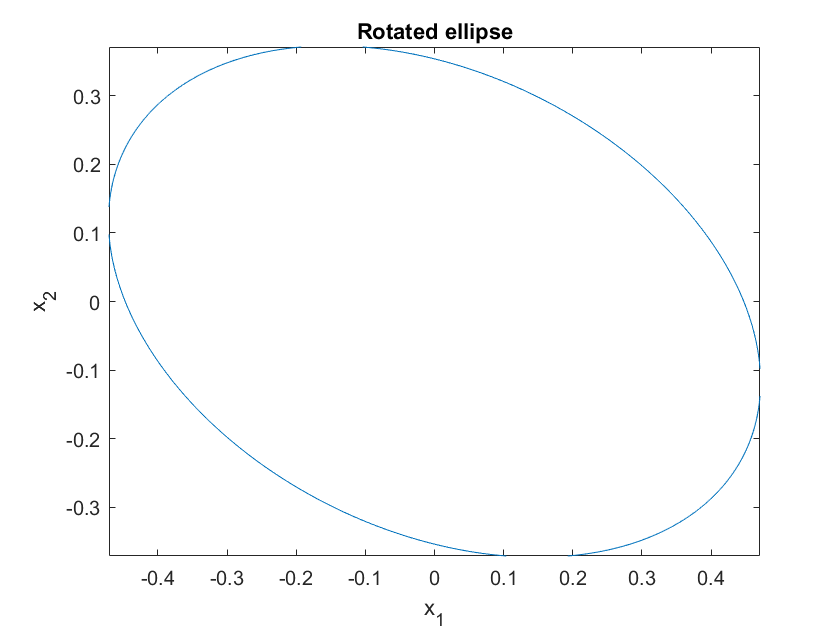

figure
x = sym('x', [2,1], 'real');
fimplicit(5*x(1)^2 + 4*x(1)*x(2) + 8*x(2)^2 - 1)
xlabel x_1, ylabel x_2
title('Rotated ellipse')

Expand your technique to allow for a more general ellipse which is also translated away from the origin:


$$A{x_1}^2 + Bx_1\,x_2 + C{x_2}^2 + Dx_1 + Ex_2 + F = 0$$
